Импорт данных из файлов

spectra = importdata('spectra.csv');
starNames = importdata('star_names.csv');
lambdaStart = importdata('lambda_start.csv');
lambdaDelta = importdata('lambda_delta.csv');

Определение констант

lambdaPr = 656.28; %нм
speedOfLight = 299792.458; %км/c

Определение диапазона длин волн

nObs = size(spectra, 1);
lambdaEnd = lambdaStart + (nObs - 1) * lambdaDelta;
lambda = (lambdaStart : lambdaDelta : lambdaEnd)';

Расчёт скорости звёзд относительно земли

nStars = size(starNames, 1);
speed = zeros(1, nStars);
for i = 1:nStars
    s = spectra(:, i);
    [sHa, idx] = min(s);
    lambdaHa = lambda(idx);
    z = (lambdaHa / lambdaPr) - 1;
    speed(i) = z * speedOfLight;
end
speed = speed';
% звёзды с положительной скоростью
movaway = starNames(speed > 0);

Построение графика

fig = figure;

for i = 1:nStars
    if speed(i) > 0        
        plot(lambda, spectra(:, i), 'linewidth', 3)
    else
        plot(lambda, spectra(:, i), '--', 'linewidth', 1)
    end
    
    hold on
end

legend(starNames)

title('Спектры звёзд')
xlabel('Длина волны, нм')
ylabel(['Интенсивность излучения, эрг/см^2/с/', char(197)])
text(lambdaStart * 7 / 8 + lambdaEnd / 8, max(max(spectra) * 1.05), 'Карташов Константин Б04-005')

grid on

set(fig, 'visible', 'on')

Сохранение графика

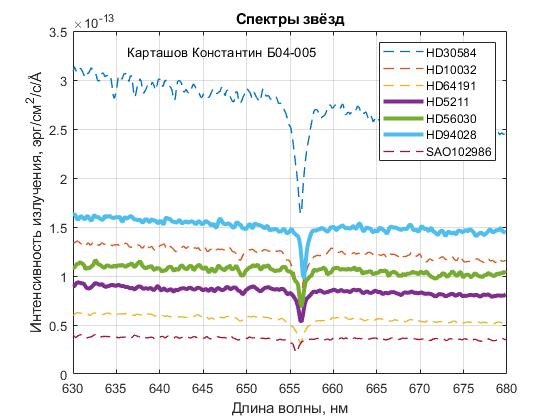

saveas(fig, 'figure.png')